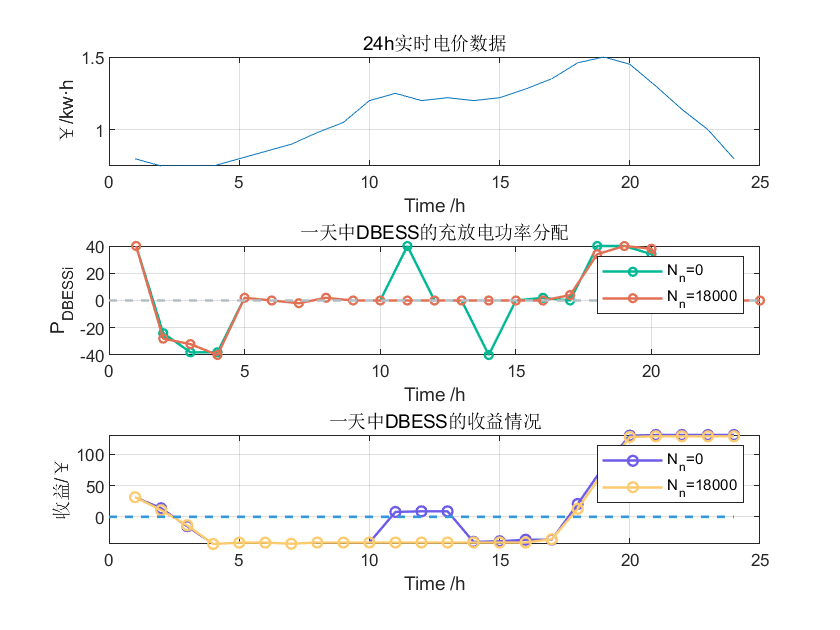

t_vis=1:24;
% r_sum=ones(1,length(t_vis));
% gain_vis=ones(1,length(t_vis));
% for j=1:24
%     r_sum(j)=sum(r_vis(1,1:j));
%     gain_vis(j)=r_sum(j)-cost_vis(1,j)-cost_ag_vis(1,j);
% end

figure(1)
subplot(3,1,1)
plot(t_vis,p)
grid on
xlabel('Time /h')
ylabel('￥/kw·h')
title('24h实时电价数据')

subplot(3,1,2)
plot(t_vis,P1(1,:),'LineWidth',1.2,'Color','#00b894','Marker',"o","MarkerSize",4);
hold on
plot(t_vis,P2(1,:),'LineWidth',1.2,'Color','#e17055','Marker',"o","MarkerSize",4);
line([0,24],[0,0],"Color",'#b2bec3',"LineWidth",1.3,'LineStyle','--')
grid on
xlabel('Time /h')
ylabel('P_{DBESS}_i')
title('一天中DBESS的充放电功率分配')
axis([0,24,-P_N,P_N])
legend('N_n=0','N_n=18000')

subplot(3,1,3)
plot(t_vis,gain1(1,:),'LineWidth',1.2,'Color','#6c5ce7','Marker',"o","MarkerSize",5);
hold on
plot(t_vis,gain2(1,:),'LineWidth',1.2,'Color','#fdcb6e','Marker',"o","MarkerSize",5);
line([0,24],[0,0],"Color",'#3498db',"LineWidth",1.3,'LineStyle','--')
grid on
xlabel('Time /h')
ylabel('收益/￥')
title('一天中DBESS的收益情况')
legend('N_n=0','N_n=18000')


% %收敛过程可视化
% figure(2)
%     %画动态图像
%     for i=1:n-1
%         subplot(2,1,1)
%         plot(t_vis,p)
%         grid on
%         xlabel('Time /h')
%         ylabel('￥/kw·h')
%         title('24h实时电价数据')
%         subplot(2,1,2)
%         if i==n-1
%             plot(t_vis,P_gif(i,:),'LineWidth',1.2,'Color','#eb4d4b','Marker',"o","MarkerSize",5);
%         else
%             plot(t_vis,P_gif(i,:),'LineWidth',1.2,'Color','#54a0ff','Marker',"o","MarkerSize",5);
%         end
%         hold on
%         line([0,24],[0,0],"Color",'#e74c3c',"LineWidth",1.3,'LineStyle','--')
%         grid on
%         xlabel('Time /h')
%         ylabel('P_{DBESS}_i')
%         title('一天中DBESS的充放电功率分配')
%         axis([0,24,-P_N,P_N])
%         hold off
%        %储存动图
%         frame = getframe(figure(2));
%         im{i} = frame2im(frame);
%         filename = 'DBESS1.gif'; 
%         [A,map] = rgb2ind(im{i},256);
%         if i == 1
%             imwrite(A,map,filename,'gif','LoopCount',Inf,'DelayTime',0);
%         elseif i==n-1
%             imwrite(A,map,filename,'gif','WriteMode','append','DelayTime',2);
%         else
%             imwrite(A,map,filename,'gif','WriteMode','append','DelayTime',0);
%         end
%     end 